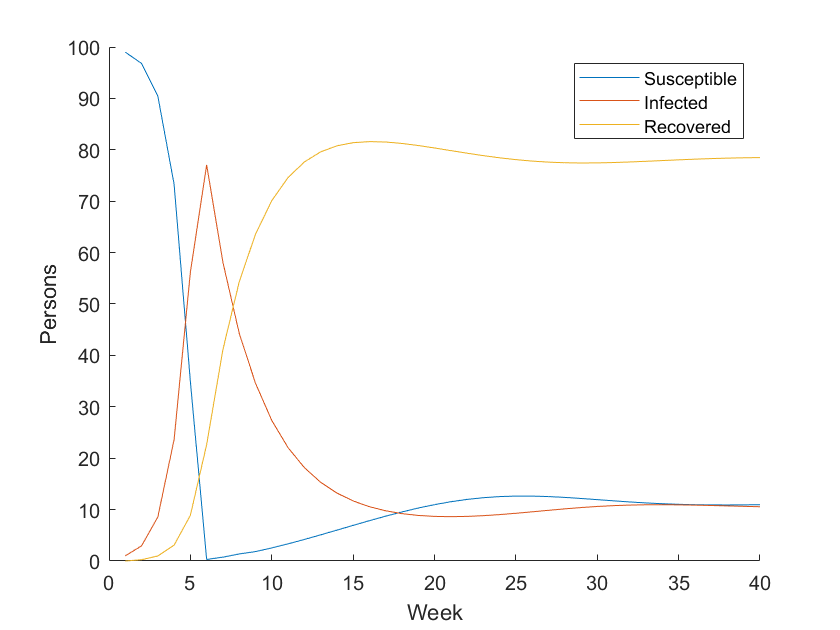

% Define initial state
% A population of 100 persons, 99 susceptible and 1 infectious
s_0 = 99;
i_0 = 1;
r_0 = 0;

% Let's interpret t to be Weeks; thus
% Infection rate: Each infected person has a chance to infect 1 susceptible
%                 person out of 50
% Recovery rate: The infection lasts 4 weeks before recovery
beta = 1 / 45;
gamma = 1/4;
alpha = 1/30;
num_week = 40;
% Run simulation
[S, I, R, W, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);

% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
%(s, i, r, beta, r_time, s_time, infected_list, step)
hold off;

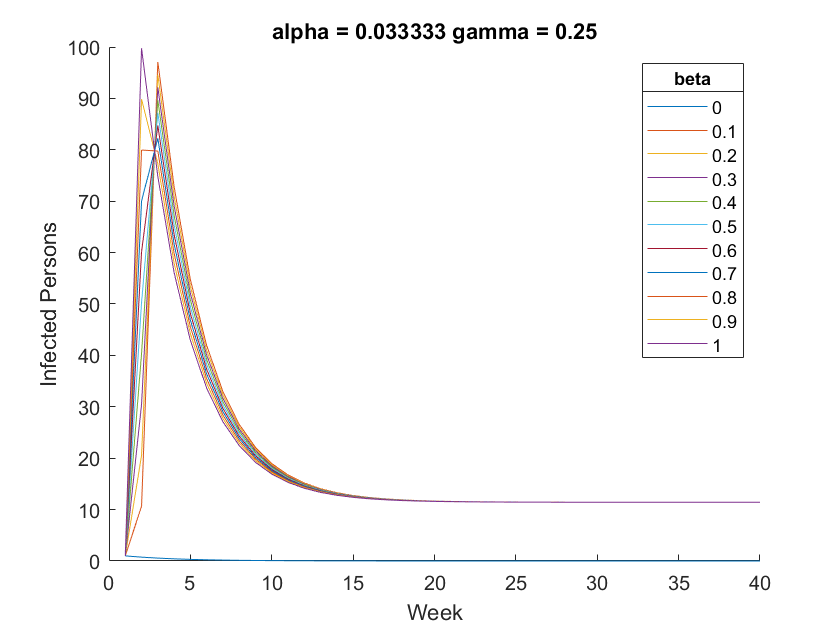



%run beta_sweep
[I,W,w] = beta_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);

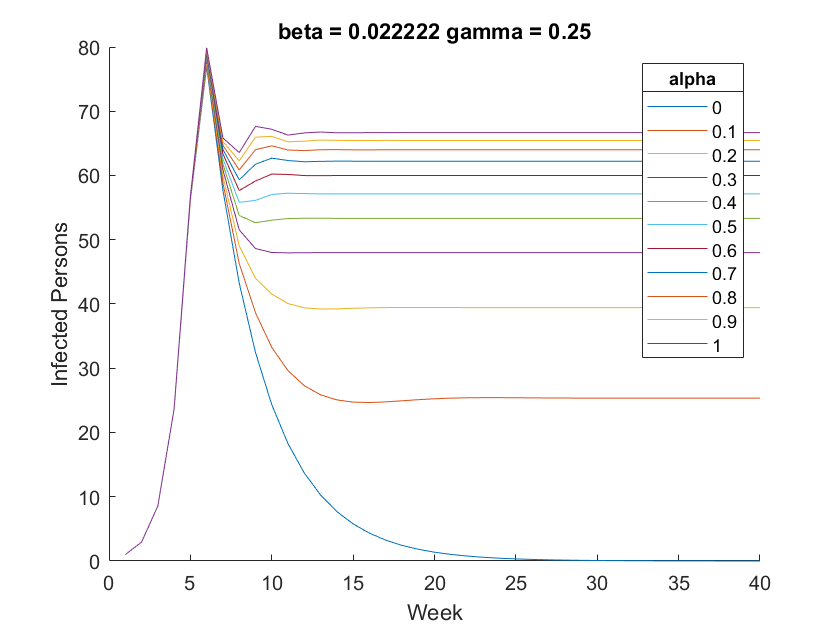

[I,W,w] = alpha_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);

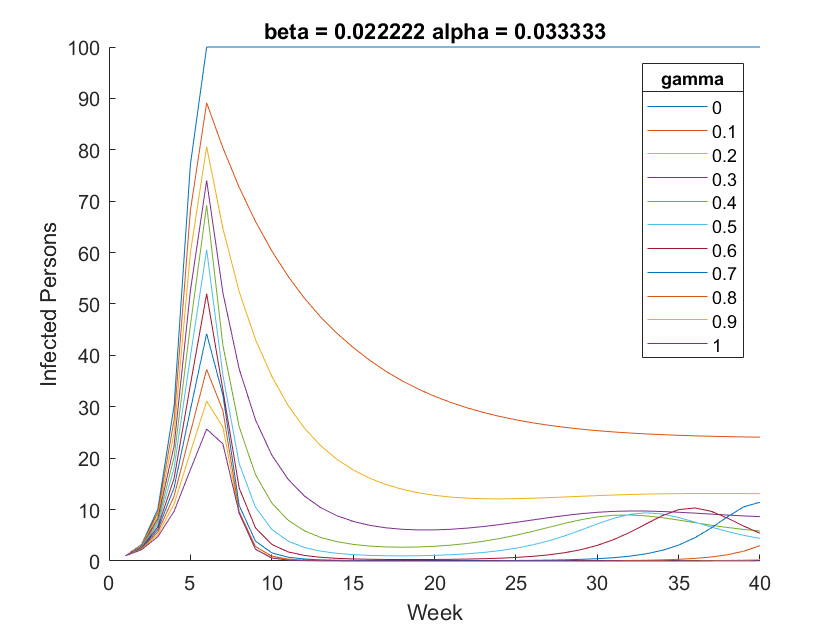

[I,W,w] = gamma_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);